# Trajectories using Puma 560

## Start and end poses

clear
mdl_puma560

Consider the end-effector of the Puma 560 moving between two  cartesian poses, which describe points in the xy-plane with different end-effector orientations.

T1 = SE3(0.4,0.2,0)*SE3.Rx(pi);
T2 = SE3(0.4,-0.2,0)*SE3.Rx(pi/2);

## Joints poses

The joint coordinate vectors associated with these poses are:

q1 = p560.ikine6s(T1);
q2 = p560.ikine6s(T2);

We require the motion to occur over a time period of 2 seconds in 50 ms time steps

t = [0:0.05:2]';

## Joint space interpolation

A joint-space trajectory is formed by smoothly interpolating between the joint configurations q1 and q2. Previously we used the functions 'tpoly' or 'lspb' f in conjunction with the multi-axis driver function 'mtraj'.

All of them results in a 50 × 6 matrix q with one row per time step and one column per joint

q_tp = mtraj(@tpoly, q1, q2, t)

q_tp =     3.2631    2.0791    0.5992   -0.0000    0.4633    0.1215
    3.2629    2.0791    0.5992   -0.0003    0.4634    0.1217
    3.2620    2.0791    0.5992   -0.0027    0.4642    0.1228
    3.2596    2.0791    0.5992   -0.0087    0.4662    0.1257
    3.2551    2.0791    0.5992   -0.0199    0.4700    0.1310
    3.2482    2.0791    0.5992   -0.0373    0.4758    0.1394
    3.2384    2.0791    0.5992   -0.0618    0.4840    0.1512
    3.2255    2.0791    0.5992   -0.0940    0.4949    0.1667
    3.2094    2.0791    0.5992   -0.1344    0.5084    0.1861
    3.1899    2.0791    0.5992   -0.1832    0.5248    0.2096



q_ls = mtraj(@lspb, q1, q2, t)

q_ls =     3.2631    2.0791    0.5992   -0.0000    0.4633    0.1215
    3.2618    2.0791    0.5992   -0.0033    0.4644    0.1231
    3.2579    2.0791    0.5992   -0.0131    0.4677    0.1278
    3.2513    2.0791    0.5992   -0.0294    0.4732    0.1356
    3.2422    2.0791    0.5992   -0.0522    0.4808    0.1466
    3.2305    2.0791    0.5992   -0.0816    0.4907    0.1607
    3.2161    2.0791    0.5992   -0.1175    0.5028    0.1780
    3.1992    2.0791    0.5992   -0.1599    0.5170    0.1984
    3.1796    2.0791    0.5992   -0.2089    0.5334    0.2219
    3.1575    2.0791    0.5992   -0.2644    0.5521    0.2486


## Trajectory

Plotting the results: Animation

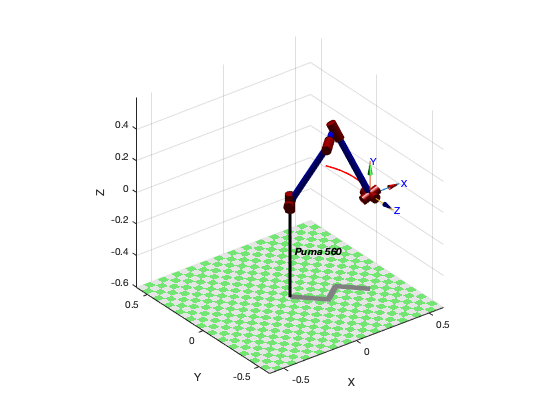

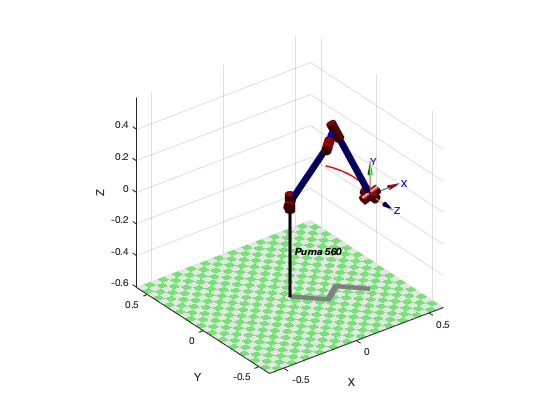

clf
p560.plot(q_tp,'zoom',2,'trail', {'r', 'LineWidth', 1.5},...
          'workspace',[-0.6 0.6 -0.6 0.6 -0.6 0.6])      

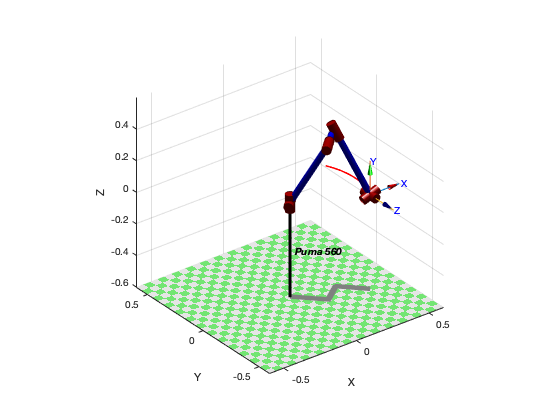

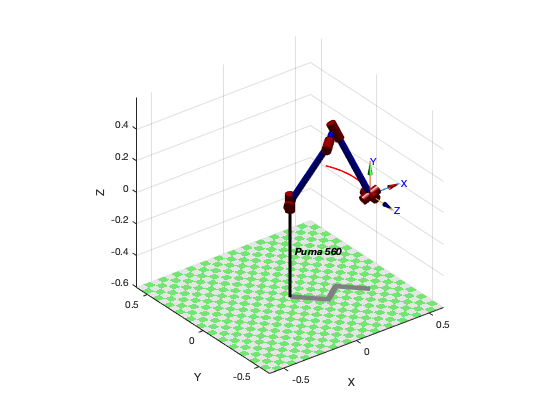

p560.plot(q_ls,'zoom',2,'trail', {'r', 'LineWidth', 1.5},...
          'workspace',[-0.6 0.6 -0.6 0.6 -0.6 0.6]) 

## Optimized Join trajectory 'jtraj'

This is equivalent to 'mtraj' with 'tpoly' interpolation but optimized for the multi-axis case and also allowing initial and final velocity to be set using additional  arguments.

You can invoque it using both: joint space interpolation or the frame description

qj = jtraj(q1, q2, t);

[q,qd,qdd] = jtraj(q1, q2, t);

qj = p560.jtraj(T1, T2, t)

qj =     3.2631    2.0791    0.5992   -0.0000    0.4633    0.1215
    3.2629    2.0791    0.5992   -0.0003    0.4634    0.1217
    3.2620    2.0791    0.5992   -0.0027    0.4642    0.1228
    3.2596    2.0791    0.5992   -0.0087    0.4662    0.1257
    3.2551    2.0791    0.5992   -0.0199    0.4700    0.1310
    3.2482    2.0791    0.5992   -0.0373    0.4758    0.1394
    3.2384    2.0791    0.5992   -0.0618    0.4840    0.1512
    3.2255    2.0791    0.5992   -0.0940    0.4949    0.1667
    3.2094    2.0791    0.5992   -0.1344    0.5084    0.1861
    3.1899    2.0791    0.5992   -0.1832    0.5248    0.2096


Plotting the results: understanding the movements. same animation as before

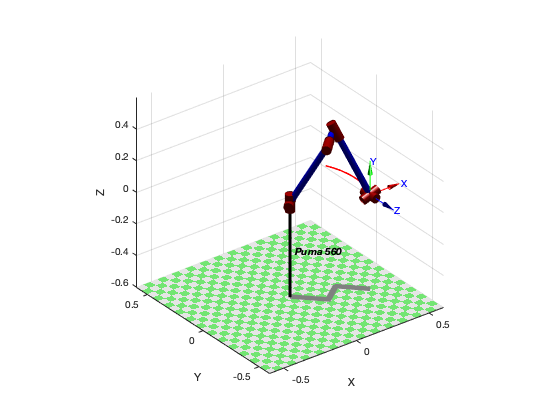

p560.plot(qj,'zoom',2,'trail', {'r', 'LineWidth', 1.5},...
          'workspace',[-0.6 0.6 -0.6 0.6 -0.6 0.6]) 

## Visualizing joint interpolation

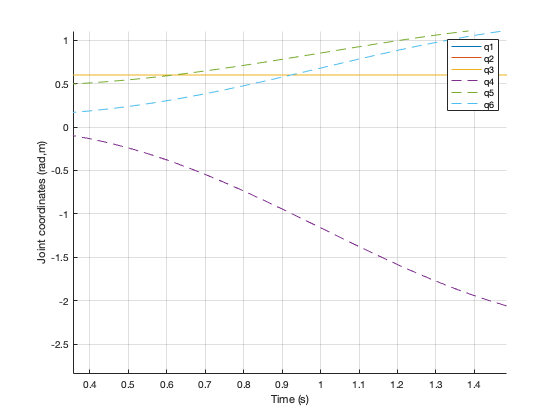

clf % clear the current figure window
qplot(t, qj);

## Trajectory data

### Position. 2D

clf
T = p560.fkine(qj);
p = T.transl;
about(p)

p [double] : 41x3 (984 bytes)


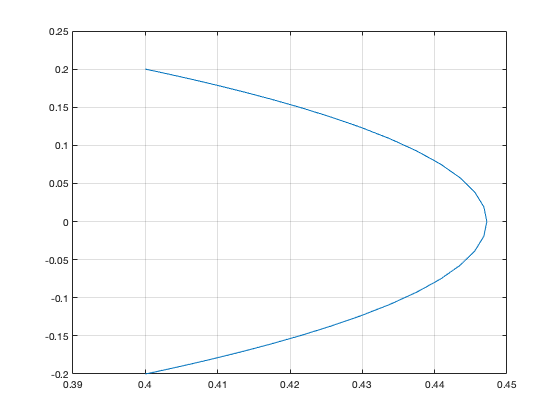

plot(p(:,1), p(:,2))
grid on

### Displacement profile

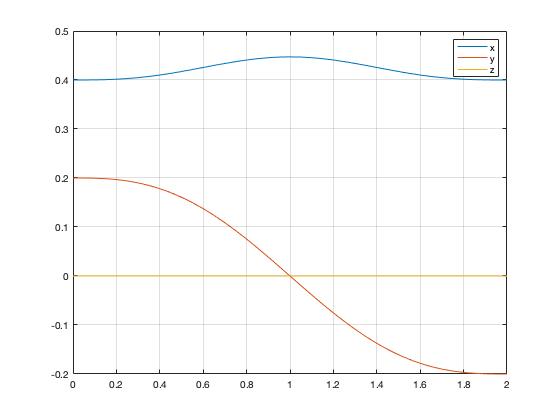

plot(t,p)
grid on
legend('x','y','z')

### End effector orientation

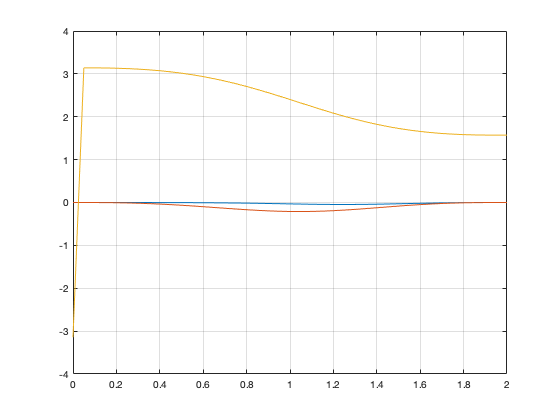

plot(t, T.torpy('xyz'))
grid on

## Cartesian motion

### Position

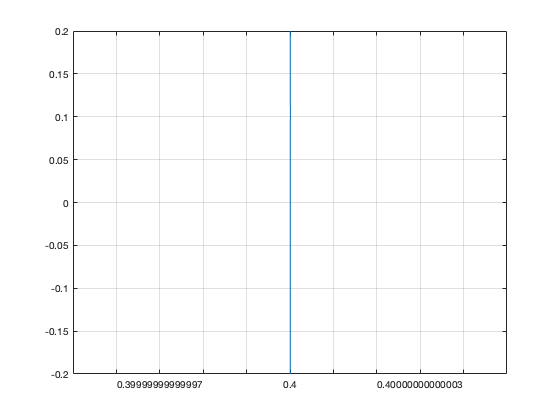

Ts = ctraj(T1,T2,length(t));
p = Ts.transl;
plot(p(:,1), p(:,2))
grid on

### Displacement profile

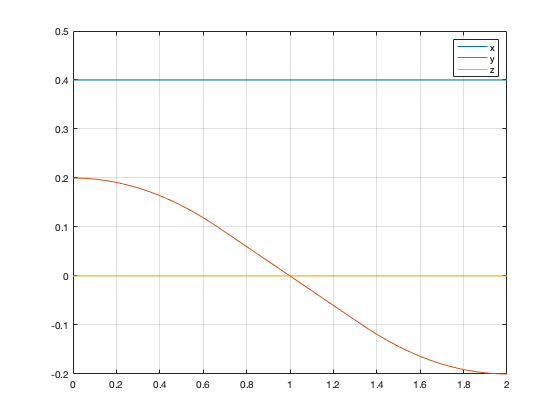

plot(t, p);
grid on
legend('x','y','z')

## Visualizing orientation

figure
p560.plot(p560.ikine6s(T1))
rpy1=T1.torpy('xyz')

rpy1 =          0         0   -3.1416


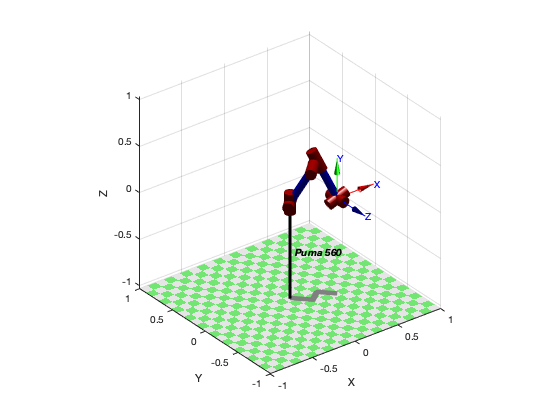

p560.plot(p560.ikine6s(T2))

rpy2=T2.torpy('xyz')

rpy2 =          0         0    1.5708


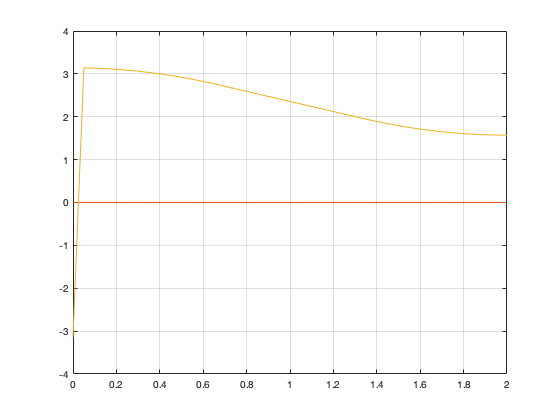

plot(t, Ts.torpy('xyz'));
grid on

## Trajectory

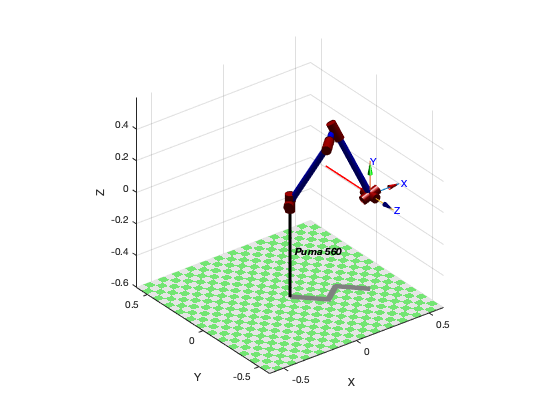

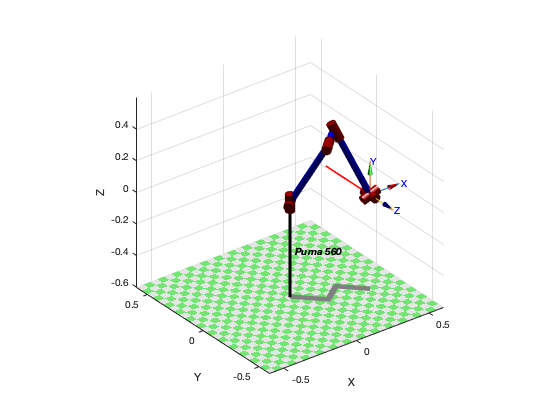

qc = p560.ikine6s(Ts);
clf
p560.plot(qc,'zoom',2,'trail', {'r', 'LineWidth', 1.5},...
          'workspace',[-0.6 0.6 -0.6 0.6 -0.6 0.6])

### Visualizing joint interpolation

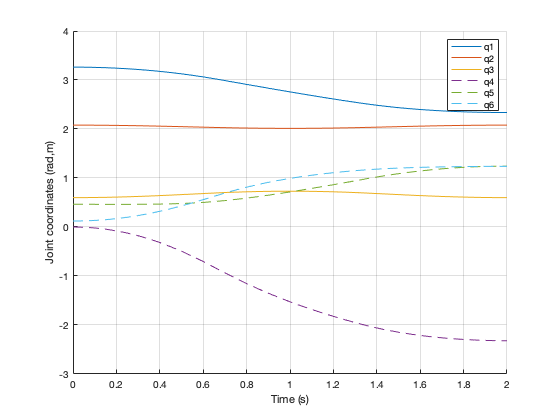

figure
qplot(t,qc)